Curve Fitting - approximating polynomial equations for our data

- Best fit curve for the data

- polyfit() - calculates coefficients of the best fit curve

- polyval() - takes in a vector of coefficients and makes a polynomial

Curve fitting to data that were the curve is known (porabola)

figure
hold on

%Set x values
x = -5:5

%Plot the function
y = x.^2
plot(x,y,'r.', 'markersize', 48)

%Determine coeffs of the data from the data
coeffs = polyfit(x,y,2)

%Plot the fitted curve (The hard way)
y = coeffs(1)*x.^2 + coeffs(2)*x + coeffs(3)
plot(x,y,'g.-', 'linewidth', 6, 'markersize', 36)

%Plot the fitted curve (The easy way using polyval() )
y = polyval(coeffs, x)
plot(x,y,'b.-', 'linewidth', 3, 'markersize', 24)

%Plot annotations
axis tight
title('Curve fitting to known data points - Parabola')
xlabel('x-axis')
ylabel('y-axis')



Curve fitting to data where the curve is unknown

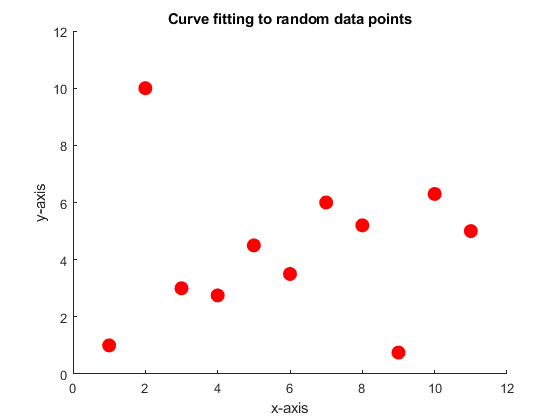

figure
hold on

x = 1:11;
y = [1 10 3 2.75 4.5 3.5 6 5.2 .75 6.3 5];
plot(x,y,'r.', 'markersize', 36)
axis([0 12 0 12])
title('Curve fitting to random data points')
xlabel('x-axis')
ylabel('y-axis')

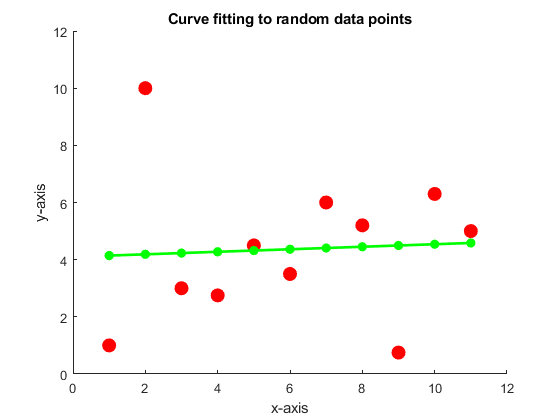


%First order curve fitting
coeff = polyfit(x, y, 1);
thisy = polyval(coeff, x);
plot(x,thisy,'g.-', 'linewidth', 2,'markersize', 24)

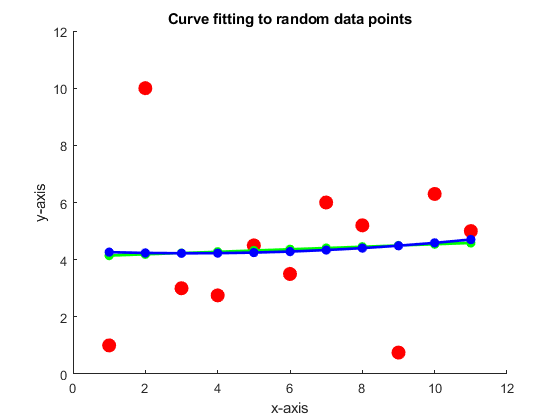


%Second order curve fitting
coeff = polyfit(x, y, 2);
thisy = polyval(coeff, x);
plot(x,thisy,'b.-', 'linewidth', 2,'markersize', 24)

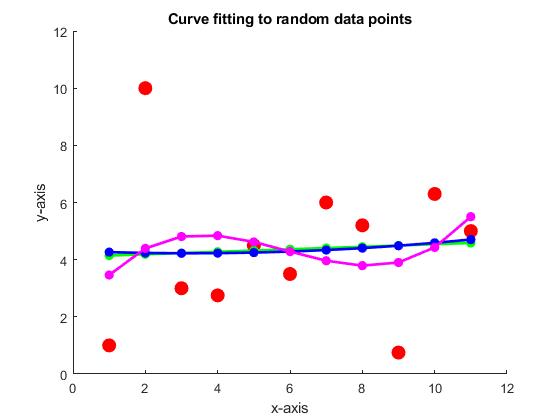


%Third order curve fitting
coeff = polyfit(x, y, 3);
thisy = polyval(coeff, x);
plot(x,thisy,'m.-', 'linewidth', 2,'markersize', 24)

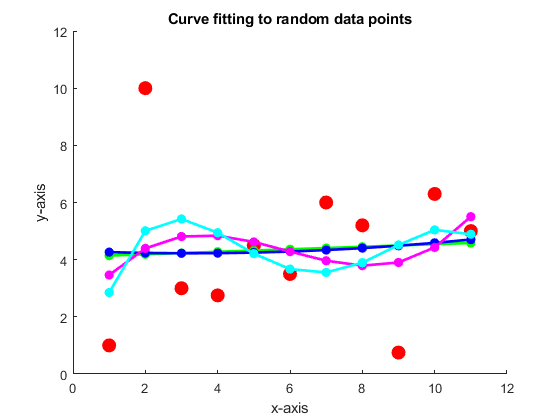


%Fourth order curve fitting
coeff = polyfit(x, y, 4);
thisy = polyval(coeff, x);
plot(x,thisy,'c.-', 'linewidth', 2,'markersize', 24)

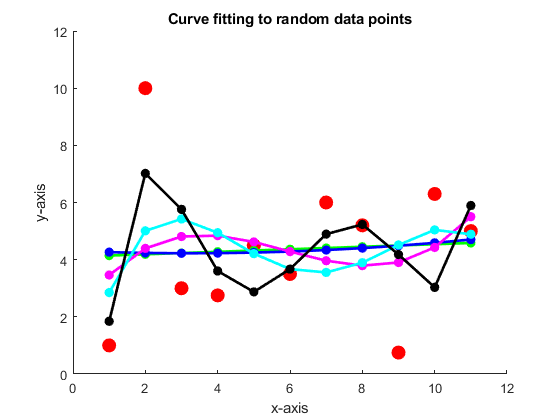


%Fifth order curve fitting
coeff = polyfit(x, y, 5);
thisy = polyval(coeff, x);
plot(x,thisy,'k.-', 'linewidth', 2,'markersize', 24)

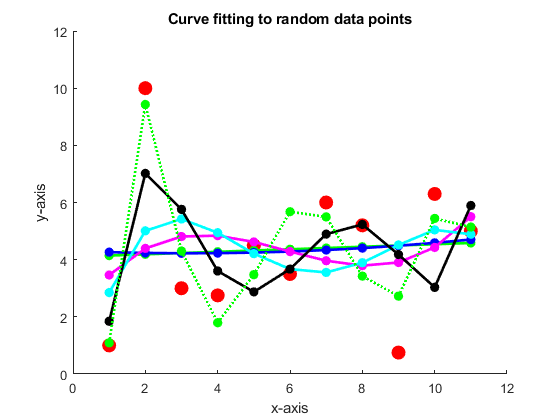

%Sixh order curve fitting
coeff = polyfit(x, y, 6);
thisy = polyval(coeff, x);
plot(x,thisy,'g.:', 'linewidth', 2,'markersize', 24)

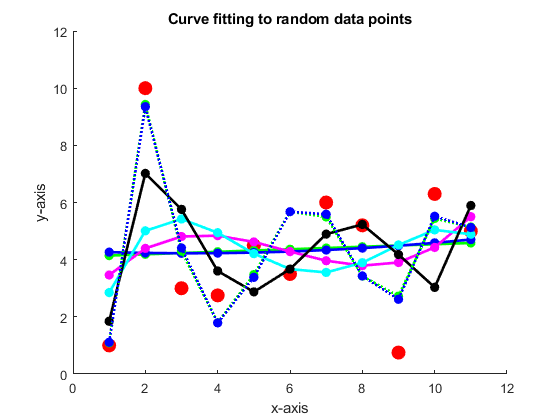


%Seventh order curve fitting
coeff = polyfit(x, y, 7);
thisy = polyval(coeff, x);
plot(x,thisy,'b.:', 'linewidth', 2,'markersize', 24)


%Eighth order curve fitting
coeff = polyfit(x, y, 8);

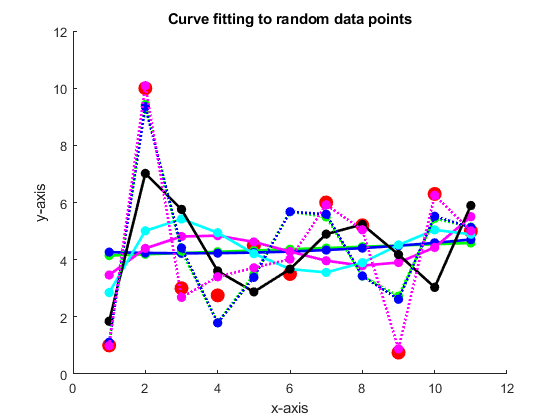

thisy = polyval(coeff, x);
plot(x,thisy,'m.:', 'linewidth', 2,'markersize', 24)


%Nineth order curve fitting
coeff = polyfit(x, y, 9);

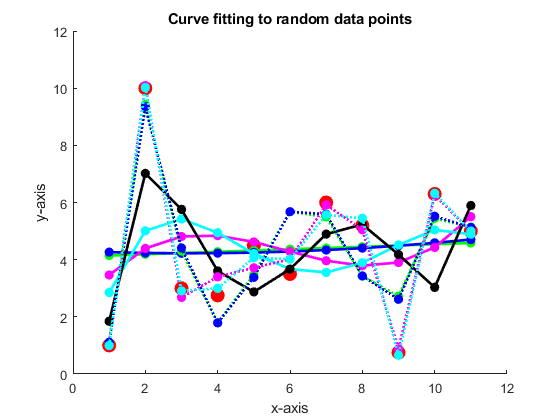

thisy = polyval(coeff, x);
plot(x,thisy,'c.:', 'linewidth', 2,'markersize', 24)

%Tenth order curve fitting
coeff = polyfit(x, y, 10);

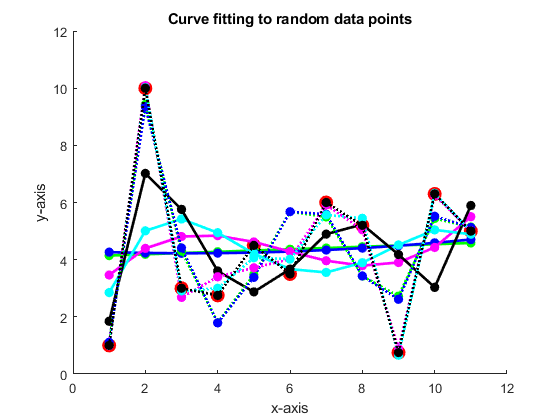

thisy = polyval(coeff, x);
plot(x,thisy,'k.:', 'linewidth', 2,'markersize', 24)